# [Solution] iTEBD: Hastings' method, orthonormalization

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the function for Hastings' version of iTEBD

Check out the funciton `iTEBD_GS_Hastings.m` under the `DMRG` sub-directory. Compare with your implementation of `iTEBD_GS_Hastings_Ex.m`!

## Solution to Exercise (b): Complete the function for the orthonormalization

Check out the funciton `ortho_Orus.m` under the `DMRG` sub-directory. Compare with your implementation of `ortho_Orus_Ex.m`!

To see how `ortho_Orus.m` improves the normalization properties, we consider the following iTEBD calculation.

clear

% iTEBD parameters
Nkeep = 30;
tau_ini = 1; % initial imaginary time step size
tau_fin = 1e-6; % final imaginary time step size
Nstep = 2e3; % number of imaginary time steps
taus = tau_ini*((tau_fin/tau_ini).^linspace(0,1,Nstep));
% discrete imaginary time steps; decays slowly but exponentially

% Local operators
[S,I] = getLocalSpace('Spin',1);

% Heisenberg interaction as two-site gate S*S'
H = contract(S,3,3,permute(conj(S),[2 1 3]),3,3);

% Initialize with random Lambda and Gamma
Lambda_init = cell(1,2);
Gamma_init = cell(1,2);
for itn = (1:numel(Lambda_init))
    Lambda_init{itn} = rand(Nkeep,1);
    Gamma_init{itn} = rand(Nkeep,Nkeep,size(I,2));
end

% iTEBD ground state search
[Lambda,Gamma,Eiter] = iTEBD_GS_Vidal(Lambda_init,Gamma_init,H,Nkeep,taus);

22-10-06 15:38:54 | iTEBD ground state search: Nkeep = 30, # of imag. time steps = 2000
22-10-06 15:38:57 | #500/2000, E = -1.3992815
22-10-06 15:38:59 | #1000/2000, E = -1.4014172
22-10-06 15:39:02 | #1500/2000, E = -1.4014805
22-10-06 15:39:04 | #2000/2000, E = -1.4014825
Elapsed time: 10.3s, CPU time: 105.5s, Avg # of cores: 10.25
22-10-06 15:39:04 | Memory usage : 1.86GiB


To be used as the input to `ortho_Orus.m`, we compute a "coarse-grained" $\Gamma$ tensor (according to [[R. Orus and G. Vidal, Phys. Rev. B **78**, 155117 (2008)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.78.155117)]) for the two-site unit cell, by performing a contraction of type `Gamma{1}*Lambda{1}*Gamma{2}`. We merge the two physical legs of the coarse-grained $\Gamma$ tensor for future convenience. 

Gamma2 = contract(Gamma{1},3,2,diag(Lambda{2}),2,1,[1 3 2]);
Gamma2 = contract(Gamma2,3,2,Gamma{2},3,1,[1 3 2 4]);

% isometry that merges the two physical legs of Gamma2
Aloc = getIdentity(Gamma2,3,Gamma2,4);
Gamma2 = contract(Gamma2,4,[3 4],conj(Aloc),3,[1 2]);

Then `Lambda{2}` would be the singular value tensor that contracts to the left and right legs of the "coarsed-grained" $\Gamma$ tensor `Gamma2`.

Now we orthonormalize those tensors.

[Lambda_orth,Gamma_ortho] = ortho_Orus (Lambda{2},Gamma2);

Check whether the `[Lambda,Gamma]_ortho` lead to left- and right-normalized tensors.

% check left-normalization
M = contract(diag(Lambda_orth),2,2,Gamma_ortho,3,1);
M = contract(conj(M),3,[1 3],M,3,[1 3]);
disp(M(1:5,1:5))

    1.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000    1.0000    0.0000         0    0.0000
   -0.0000    0.0000    1.0000   -0.0000    0.0000
    0.0000         0   -0.0000    1.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000    1.0000



disp(max(max(abs(M-eye(size(M))))));

   5.4065e-07



% check right-normalization
M = contract(Gamma_ortho,3,2,diag(Lambda_orth),2,1,[1 3 2]);
M = contract(conj(M),3,[2 3],M,3,[2 3]);
disp(M(1:5,1:5))

    1.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000    1.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    1.0000         0   -0.0000
    0.0000   -0.0000         0    1.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000    1.0000



disp(max(max(abs(M-eye(size(M))))));

   5.4065e-07



Aa a reference, we do the same analysis for the tensors before the orthonormalization.

% check left-normalization
M = contract(diag(Lambda{2}),2,2,Gamma2,3,1);
M = contract(conj(M),3,[1 3],M,3,[1 3]);
disp(M(1:5,1:5))

    1.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000    0.0000   -0.0000
   -0.0000    0.0000    1.0007    0.0000    0.0000
    0.0000    0.0000    0.0000    1.0007   -0.0000
   -0.0000   -0.0000    0.0000   -0.0000    1.0007



disp(max(max(abs(M-eye(size(M))))));

    0.0120



% check right-normalization
M = contract(Gamma2,3,2,diag(Lambda{2}),2,1,[1 3 2]);
M = contract(conj(M),3,[2 3],M,3,[2 3]);
disp(M(1:5,1:5))

    1.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000    0.0000   -0.0000
   -0.0000    0.0000    1.0007    0.0000    0.0000
    0.0000    0.0000    0.0000    1.0007   -0.0000
   -0.0000   -0.0000    0.0000   -0.0000    1.0007



disp(max(max(abs(M-eye(size(M))))));

    0.0120



Without the orthonormalization, the deviation from the identity is larger by several orders of magnitudes.

## Solution to Exercise (c): Correlation length of the spin-1 Heisenberg model

Here we explain how to analyze transfer operators, by continuing from the iTEBD calculation in the demonstration above. We construct the transfer operator $\hat{T}$ that "transfers" the bond spaces from the right. For this, we use the approximately right-normalized ket tensor of `Gamma*Lambda` type.

M = contract(Gamma_ortho,3,2,diag(Lambda_orth),2,1,[1 3 2]);
T = contract(conj(M),3,3,M,3,3,[3 1 4 2]);
T = reshape(T,numel(Lambda_orth)^2*[1 1]);

Diagonalize the transfer operator.

[V,D] = eig(T);
D = real(diag(D));

Here we take the real parts of the eigenvalues, since the imaginary parts are numerical noises; you can verify this by checking their magnitudes.

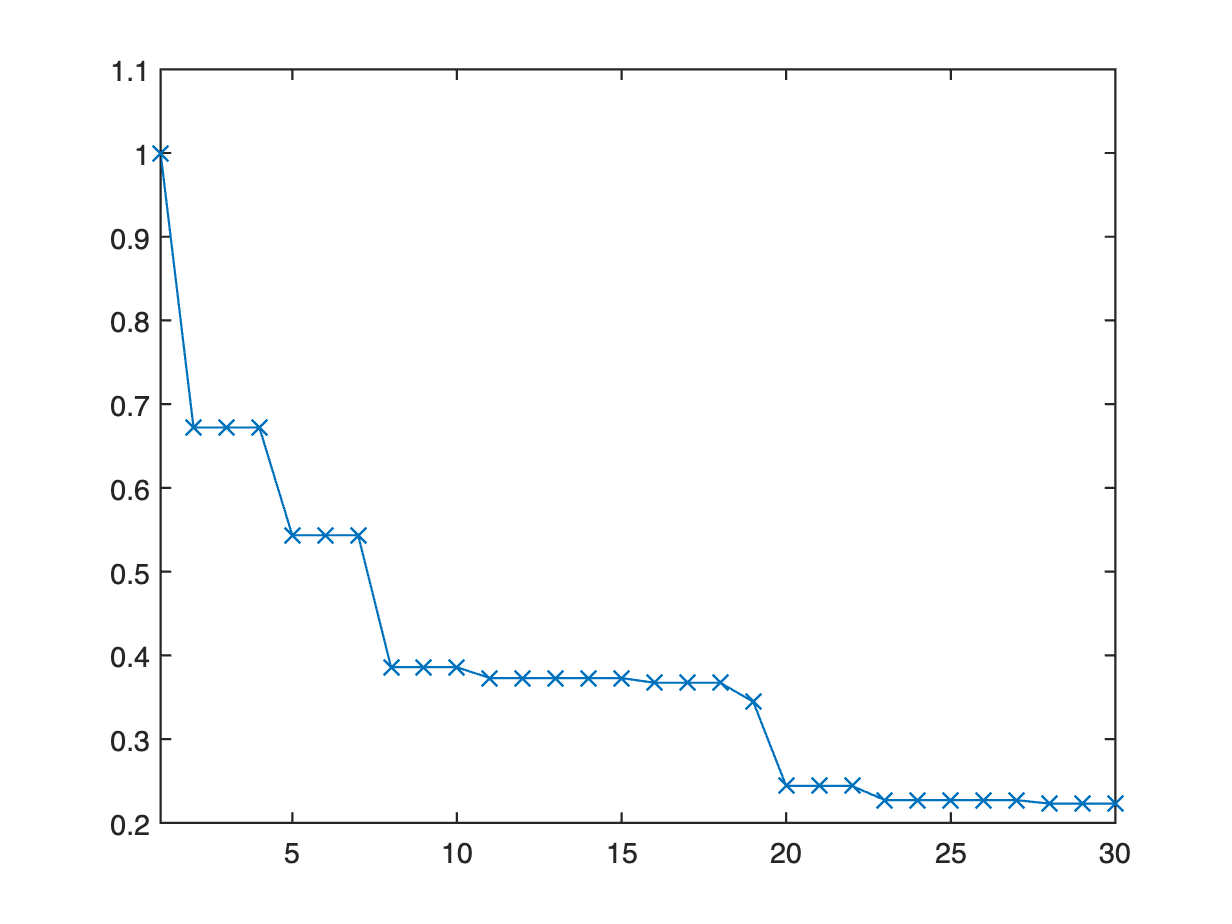

[D,ids] = sort(D,'descend');
V = V(:,ids);
figure;
plot((1:numel(D)).',D(:),'-x','LineWidth',1,'MarkerSize',10);
set(gca,'LineWidth',1,'FontSize',13,'YScale','linear','XLim',[1 30]);

The largest eigenvalue is 1, which corresponds to the right-normalization of `M`. The next largest eigenvalues, which are three-fold degenerate, govern the correlation function, as we will show below.

Then we construct the transfer operator $\hat{T}_{\hat{S}_z}$ for the spin-$z$ operator acting on an odd site (i.e., the first physical site within the unit cell) sandwiched by the ket tensor `M` and its Hermitian conjugate.

% spin operator in the physical space for *two* sites
Sz2 = contract(S(:,:,2),2,2,Aloc,3,1);
Sz2 = contract(conj(Aloc),3,[1 2],Sz2,3,[1 2]);

% transfer operator for the Sz operator at an odd site
MSz = contract(M,3,3,Sz2,2,2);
TSz = contract(conj(M),3,3,MSz,3,3,[3 1 4 2]);
TSz = reshape(TSz,numel(Lambda_orth)^2*[1 1]);

Compute the matrix elements of $\hat{T}_{\hat{S}_z}$ in the basis of the eigenvectors of $\hat{T}$ and multiply them. The multiplied elements, i.e., $[\hat{T}_{\hat{S}_z}]_{1k} [\hat{T}_{\hat{S}_z}]_{k1}$, are the prefactors to the distance dependence $t_k^n$, where $t_k$ indicates the $k$-th eigenvalue.

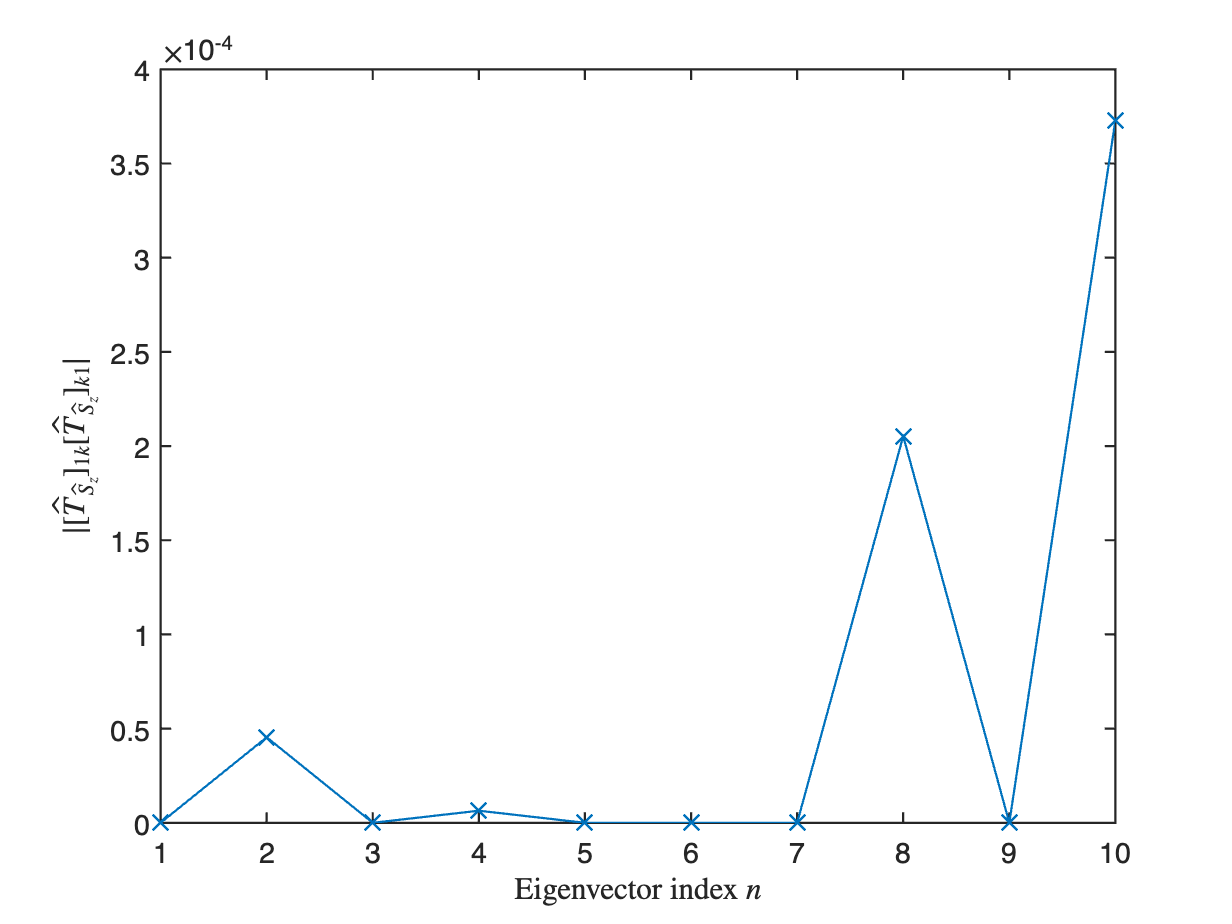

TSz_1k = V(:,1)\TSz*V;
TSz_k1 = V\TSz*V(:,1);

figure;
plot((1:numel(TSz_1k)).',real(TSz_1k(:).*TSz_1k(:)),'-x','LineWidth',1,'MarkerSize',10);
set(gca,'LineWidth',1,'FontSize',13,'Xlim',[1 10]);
ylabel('$| [\hat{T}_{\hat{S}_z}]_{1k} [\hat{T}_{\hat{S}_z}]_{k1} |$','Interpreter','latex');
xlabel('Eigenvector index $n$','Interpreter','latex');

The first prefactor, i.e., $[\hat{T}_{\hat{S}_z}]_{11} [\hat{T}_{\hat{S}_z}]_{11}$, is zero up to numerical precision noise:

disp(TSz_1k(1).*TSz_1k(1));

   5.2612e-27



Therefore the next largest eigenvalues dominate the scaling behavior for large distance $n$, as the exponential decay $t_{k}^{n/2} = \exp (-n / \xi)$ with $\xi = -2 / \ln | t_k|$ for $k = 2,3,4$. Note that the distance dependence is given by $t_k^{n/2}$, not by $t_k^n$, since we consider the transfer operators for the two-site unit cell.

disp(-2/log(D(2)));

    5.0345



Now we analyze how the correlation length $\xi$ changes with `Nkeep`. For this analysis, we decrease `tau_fin` and increase `Nstep` to get better convergence.

tau_ini = 1; % initial imaginary time step size
tau_fin = 1e-9; % final imaginary time step size
Nstep = 4e3; % number of imaginary time steps
taus = tau_ini*((tau_fin/tau_ini).^linspace(0,1,Nstep));
Nkeeps = [30 60 120];
xis = zeros(size(Nkeeps));

for itN = (1:numel(Nkeeps))
    [Lambda,Gamma,Eiter] = iTEBD_GS_Vidal(Lambda_init,Gamma_init,H,Nkeeps(itN),taus);

    Gamma2 = contract(Gamma{1},3,2,diag(Lambda{2}),2,1,[1 3 2]);
    Gamma2 = contract(Gamma2,3,2,Gamma{2},3,1,[1 3 2 4]);
    
    % isometry that merges the two physical legs of Gamma2
    Aloc = getIdentity(Gamma2,3,Gamma2,4);
    Gamma2 = contract(Gamma2,4,[3 4],conj(Aloc),3,[1 2]);

    [Lambda_orth,Gamma_ortho] = ortho_Orus (Lambda{2},Gamma2);

    M = contract(Gamma_ortho,3,2,diag(Lambda_orth),2,1,[1 3 2]);
    T = contract(conj(M),3,3,M,3,3,[3 1 4 2]);
    T = reshape(T,numel(Lambda_orth)^2*[1 1]);

    [V,D] = eigs(T,2,'lm');
    D = real(diag(D));
    [D,ids] = sort(D,'descend');

    xis(itN) = -2/log(D(2));
end

22-10-06 15:39:07 | iTEBD ground state search: Nkeep = 30, # of imag. time steps = 4000
22-10-06 15:39:09 | #500/4000, E = -1.3958268
22-10-06 15:39:12 | #1000/4000, E = -1.4011126
22-10-06 15:39:14 | #1500/4000, E = -1.4014555
22-10-06 15:39:17 | #2000/4000, E = -1.4014809
22-10-06 15:39:19 | #2500/4000, E = -1.4014828
22-10-06 15:39:22 | #3000/4000, E = -1.401483
22-10-06 15:39:24 | #3500/4000, E = -1.401483
22-10-06 15:39:27 | #4000/4000, E = -1.401483
Elapsed time: 20.27s, CPU time: 209.2s, Avg # of cores: 10.32
22-10-06 15:39:27 | Memory usage : 1.99GiB
22-10-06 15:39:27 | iTEBD ground state search: Nkeep = 60, # of imag. time steps = 4000
22-10-06 15:39:33 | #500/4000, E = -1.3958276
22-10-06 15:39:39 | #1000/4000, E = -1.4011131
22-10-06 15:39:44 | #1500/4000, E = -1.401456
22-10-06 15:39:50 | #2000/4000, E = -1.4014814
22-10-06 15:39:56 | #2500/4000, E = -1.4014833
22-10-06 15:40:02 | #3000/4000, E = -1.4014835
22-10-06 15:40:08 | #3500/4000, E = -1.4014835
22-10-06 15:40:13 | 

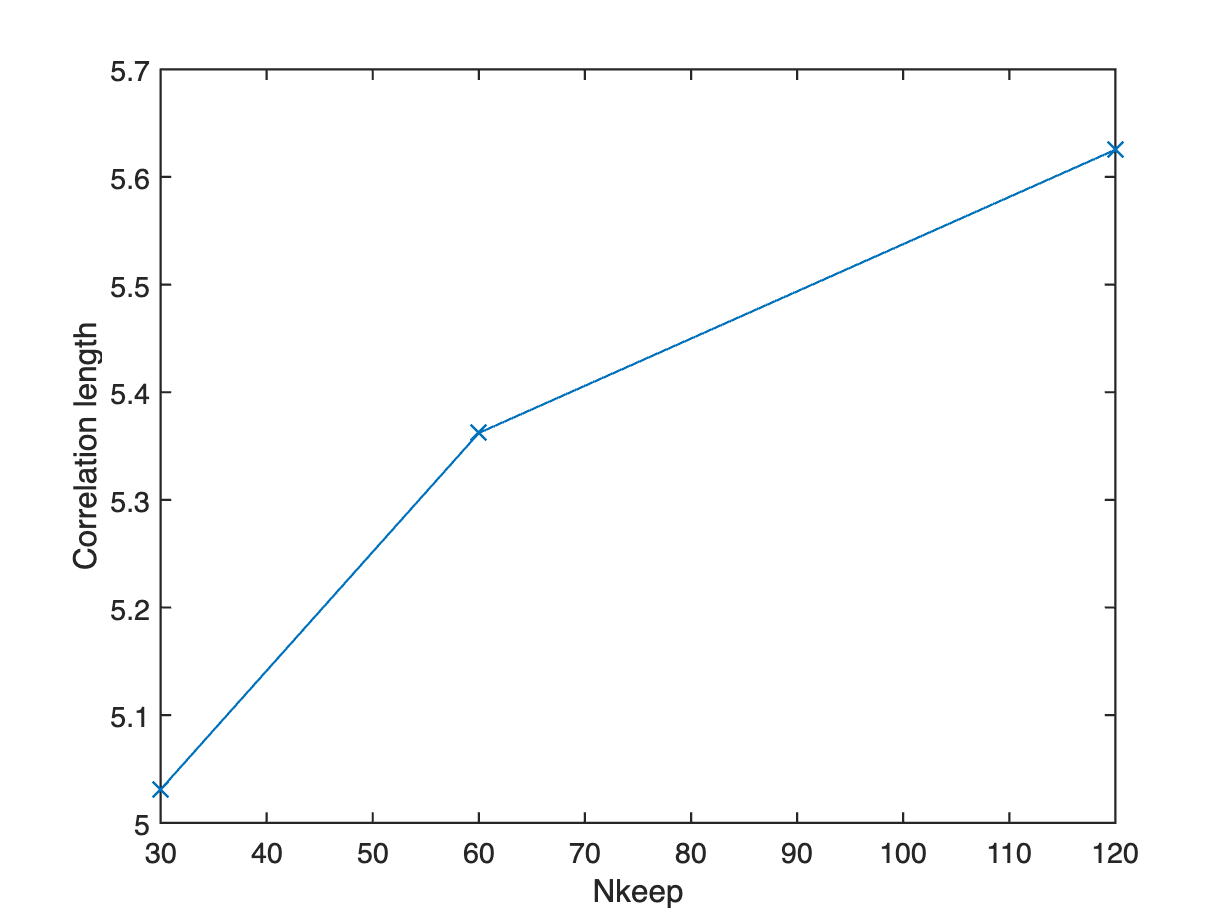


figure;
plot(Nkeeps,xis,'-x','LineWidth',1,'MarkerSize',10)
set(gca,'LineWidth',1,'FontSize',13);
ylabel('Correlation length');
xlabel('Nkeep');

We see that $\xi$ approaches to 6 as `Nkeep` increase.